# IBME CA1- Reyhane Vahedi 810195498

## Q2

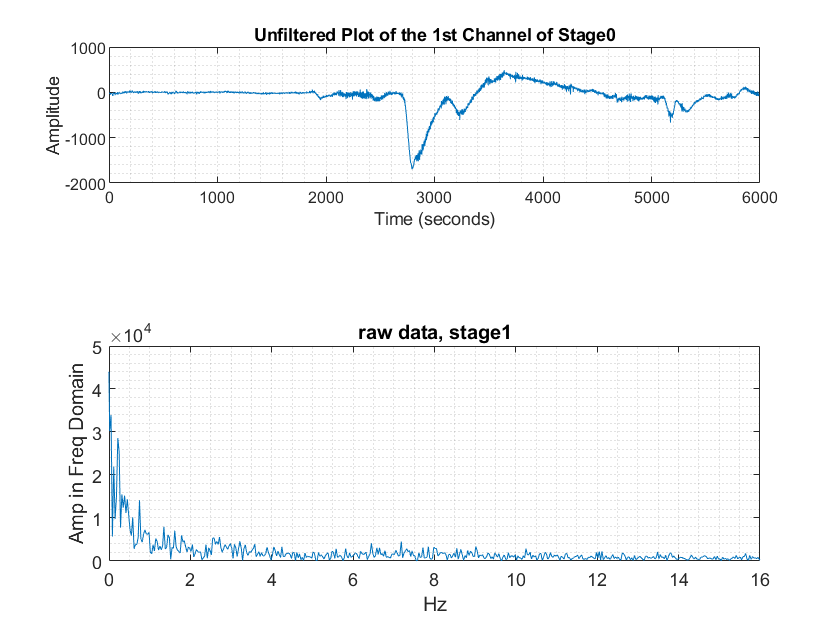

uf0= stage0.Data(:,1);
uf1=stage1.Data(:,1);
uf2=stage2.Data(:,1);
subplot(3,1,1)
plot(uf0)
title("Unfiltered Plot of the 1st Channel of Stage0");
xlabel("Time (seconds)")
ylabel("Amplitude")
grid minor

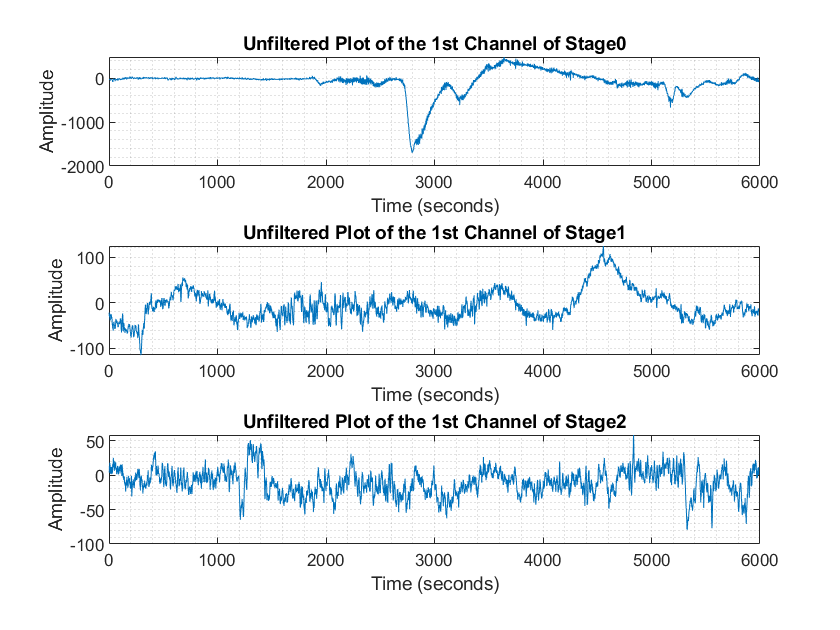

subplot(3,1,2)
plot(uf1)
title("Unfiltered Plot of the 1st Channel of Stage1");
xlabel("Time (seconds)")
ylabel("Amplitude")
grid minor
subplot(3,1,3)
plot(uf2)
title("Unfiltered Plot of the 1st Channel of Stage2");
xlabel("Time (seconds)")
ylabel("Amplitude")
grid minor

## Q2

initiating with the determination of the frequency domain sampling rate.

### ***stage 0***

figure('Position',[0,0,4e4,4e4])
sgtitle ("Stage0") 
for i = 1:7
    Fs = stage0.Fs(i);
    Ts = 1/Fs;    
    Ns = stage0.Duration;
    df = 1/(Ns * Ts);
    f = (-Ns/2:Ns/2-1)*df;
    df = fftshift(fft(stage0.Data(:,i)));
    epoch = (0:Ns-1)*Ts;    
    subplot(7,2,2*i-1)

    plot(f,abs(df))
     %ylim([0 1e4])
    xlabel("Hz");
    ylabel("Amp in Freq Domain");
    title(sprintf('raw data, Channel %d', i));
    grid minor
end

for i = 1:7
    X = stage0.Data(:,i);
    subplot(7,2,2*i)
    plot(epoch, X) 
    % ylim([-1000 1000])
    xlabel("Hz");
    ylabel("Amp");
    title(sprintf('Channel %d', i));
    grid minor
end

### *stage 1*


figure('Position',[0,0,4e4,4e4])
sgtitle ("Stage1") 
for i = 1:7
    Fs = stage1.Fs(i);
    Ts = 1/Fs;    
    Ns = stage1.Duration;
    df = 1/(Ns * Ts);
    f = (-Ns/2:Ns/2-1)*df;
    df = fftshift(fft(stage1.Data(:,i)));
    epoch = (0:Ns-1)*Ts;    
    subplot(7,2,2*i-1)

    plot(f,abs(df))
     %ylim([0 1e4])
    xlabel("Hz");
    ylabel("Amp in Freq Domain");
    title(sprintf('raw data, Channel %d', i));
    grid minor
end

for i = 1:7
    X = stage1.Data(:,i);
    subplot(7,2,2*i)
    plot(epoch, X) 
    % ylim([-1000 1000])
    xlabel("Hz");
    ylabel("Amp");
    title(sprintf('Channel %d', i));
    grid minor
end

### stage 2

figure('Position',[0,0,4e4,4e4])
sgtitle ("Stage2") 
for i = 1:7
    Fs = stage2.Fs(i);
    Ts = 1/Fs;    
    Ns = stage2.Duration;
    df = 1/(Ns * Ts);
    f = (-Ns/2:Ns/2-1)*df;
    df = fftshift(fft(stage2.Data(:,i)));
    epoch = (0:Ns-1)*Ts;    
    subplot(7,2,2*i-1)

    plot(f,abs(df))
     %ylim([0 1e4])
    xlabel("Hz");
    ylabel("Amp in Freq Domain");
    title(sprintf('raw data, Channel %d', i));
    grid minor
end

for i = 1:7
    X = stage2.Data(:,i);
    subplot(7,2,2*i)
    plot(epoch, X) 
    % ylim([-1000 1000])
    xlabel("Hz");
    ylabel("Amp");
    title(sprintf('Channel %d', i));
    grid minor
end

### *to-find*

figure('Position',[0,0,4e4,4e4])
sgtitle ("to-find") 
for i = 1:7
    Fs =to_find.Fs(i);
    Ts = 1/Fs;    
    Ns = to_find.Duration;
    df = 1/(Ns * Ts);
    f = (-Ns/2:Ns/2-1)*df;
    df = fftshift(fft(to_find.Data(:,i)));
    epoch = (0:Ns-1)*Ts;    
    subplot(7,2,2*i-1)

    plot(f,abs(df))
     %ylim([0 1e4])
    xlabel("Hz");
    ylabel("Amp in Freq Domain");
    title(sprintf('raw data, Channel %d', i));
    grid minor
end

for i = 1:7
    X = to_find.Data(:,i);
    subplot(7,2,2*i)
    plot(epoch, X) 
    % ylim([-1000 1000])
    xlabel("Hz");
    ylabel("Amp");
    title(sprintf('Channel %d', i));
    grid minor
end

### *to-find2*

figure('Position',[0,0,4e4,4e4])
sgtitle ("to-find2") 
for i = 1:7
    Fs =to_find2.Fs(i);
    Ts = 1/Fs;    
    Ns = to_find2.Duration;
    df = 1/(Ns * Ts);
    f = (-Ns/2:Ns/2-1)*df;
    df = fftshift(fft(to_find2.Data(:,i)));
    epoch = (0:Ns-1)*Ts;    
    subplot(7,2,2*i-1)

    plot(f,abs(df))
     %ylim([0 1e4])
    xlabel("Hz");
    ylabel("Amp in Freq Domain");
    title(sprintf('raw data, Channel %d', i));
    grid minor
end

for i = 1:7
    X = to_find2.Data(:,i);
    subplot(7,2,2*i)
    plot(epoch, X) 
    % ylim([-1000 1000])
    xlabel("Hz");
    ylabel("Amp");
    title(sprintf('Channel %d', i));
    grid minor
end

### *Divided wavelenghts of the 1st channel in each stage*

#### *stage0*

d = fftshift(fft(stage0.Data(:,5)));
alpha = banddivision(d,'ALPHA');
beta = banddivision(d,'BETA');
theta = banddivision(d,'THETA');
delta = banddivision(d,'DELTA');
bandwidth = [alpha,beta,theta,delta];
figure('Position',[0,0,4e4,4e4])
sgtitle ("1st channel of stage0 - divided by bandwidth")
subplot(5,1,1)
plot(epoch, stage0.Data(:,1))
xlabel("time");
ylabel("Amp");
    %title(sprintf('Channel %d', i));
title("stage0 unfiltered data");
for i = 1:4
    subplot(5,1,i+1)
    plot(epoch, ifft(ifftshift(bandwidth(:,i))))
    xlabel("time");
    ylabel("Amp");
    if i == 1  
        title("alpha");
     elseif i == 2 
        title("beta")
     elseif i == 3
        title("theta")
     elseif i == 4
        title("delta")
    end
      grid minor
end

#### *stage1*

d = fftshift(fft(stage1.Data(:,5)));
alpha = banddivision(d,'ALPHA');
beta = banddivision(d,'BETA');
theta = banddivision(d,'THETA');
delta = banddivision(d,'DELTA');
bandwidth = [alpha,beta,theta,delta];
figure('Position',[0,0,4e4,4e4])
sgtitle ("1st channel of stage1 - divided by bandwidth")
subplot(5,1,1)
plot(epoch, stage1.Data(:,1))
xlabel("time");
ylabel("Amp");
    %title(sprintf('Channel %d', i));
title("stage1 unfiltered data");
for i = 1:4
    subplot(5,1,i+1)
    plot(epoch, ifft(ifftshift(bandwidth(:,i))))
    xlabel("time");
    ylabel("Amp");
    if i == 1  
        title("alpha");
     elseif i == 2 
        title("beta")
     elseif i == 3
        title("theta")
     elseif i == 4
        title("delta")
    end
      grid minor
end

#### *stage2*

d = fftshift(fft(stage2.Data(:,5)));
alpha = banddivision(d,'ALPHA');
beta = banddivision(d,'BETA');
theta = banddivision(d,'THETA');
delta = banddivision(d,'DELTA');
bandwidth = [alpha,beta,theta,delta];
figure('Position',[0,0,4e4,4e4])
sgtitle ("1st channel of stage2 - divided by bandwidth")
subplot(5,1,1)
plot(epoch, stage2.Data(:,1))
xlabel("time");
ylabel("Amp");
    %title(sprintf('Channel %d', i));
title("stage2 unfiltered data");
for i = 1:4
    subplot(5,1,i+1)
    plot(epoch, ifft(ifftshift(bandwidth(:,i))))
    xlabel("time");
    ylabel("Amp");
    if i == 1  
        title("alpha");
     elseif i == 2 
        title("beta")
     elseif i == 3
        title("theta")
     elseif i == 4
        title("delta")
    end
      grid minor
end

#### *to-find*

d = fftshift(fft(to_find.Data(:,5)));
alpha = banddivision(d,'ALPHA');
beta = banddivision(d,'BETA');
theta = banddivision(d,'THETA');
delta = banddivision(d,'DELTA');
bandwidth = [alpha,beta,theta,delta];
figure('Position',[0,0,4e4,4e4])
sgtitle ("1st channel of to-find - divided by bandwidth")
subplot(5,1,1)
plot(epoch, to_find.Data(:,1))
xlabel("time");
ylabel("Amp");
    %title(sprintf('Channel %d', i));
title("to-find unfiltered data");
for i = 1:4
    subplot(5,1,i+1)
    plot(epoch, ifft(ifftshift(bandwidth(:,i))))
    xlabel("time");
    ylabel("Amp");
    if i == 1  
        title("alpha");
     elseif i == 2 
        title("beta")
     elseif i == 3
        title("theta")
     elseif i == 4
        title("delta")
    end
      grid minor
end

#### *to-find2*

d = fftshift(fft(to_find2.Data(:,5)));
alpha = banddivision(d,'ALPHA');
beta = banddivision(d,'BETA');
theta = banddivision(d,'THETA');
delta = banddivision(d,'DELTA');
bandwidth = [alpha,beta,theta,delta];
figure('Position',[0,0,4e4,4e4])
sgtitle ("1st channel of to-find2 - divided by bandwidth")
subplot(5,1,1)
plot(epoch, to_find2.Data(:,1))
xlabel("time");
ylabel("Amp");
    %title(sprintf('Channel %d', i));
title("to-find2 unfiltered data");
for i = 1:4
    subplot(5,1,i+1)
    plot(epoch, ifft(ifftshift(bandwidth(:,i))))
    xlabel("time");
    ylabel("Amp");
    if i == 1  
        title("alpha");
     elseif i == 2 
        title("beta")
     elseif i == 3
        title("theta")
     elseif i == 4
        title("delta")
    end
      grid minor
end

### *Q4*


   stages = [stage0,stage1,stage2]

stages = 1×3 struct array with fields:
    EpochNum
    Duration
    StartSample
    Stage
    ChanLabel
    Fs
    Data


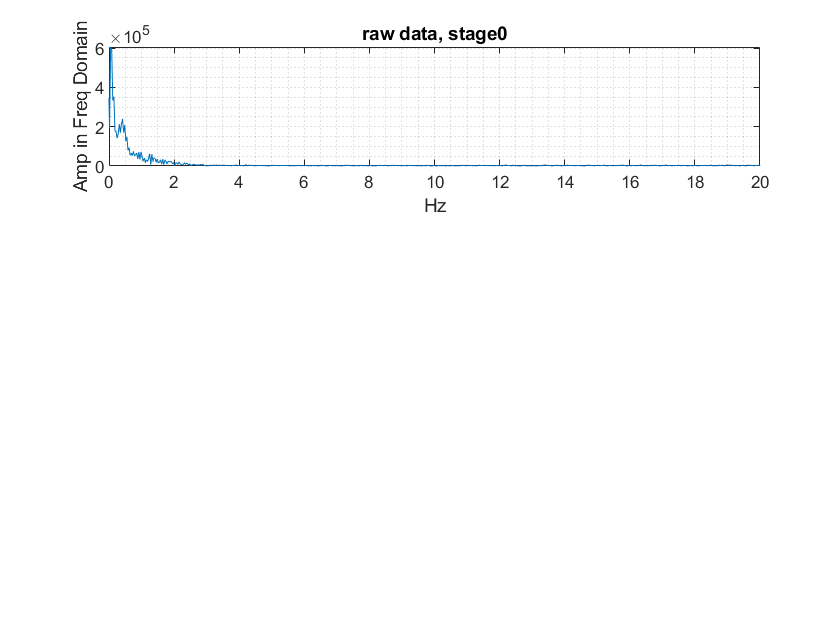

   for j = 1:3
    Fs = stages(j).Fs(1);
    Ts = 1/Fs;    
    Ns = stages(j).Duration;
    df = 1/(Ns * Ts);
    f = (-Ns/2:Ns/2-1)*df;
    df = fftshift(fft(stages(j).Data(:,1)));
    epoch = (0:Ns-1)*Ts;    
    subplot(3,1,j)
    %if i == 3 
   %ff=f(1, 1:5988)
   %dff=df(1:5988, 1)
    %plot(ff,abs(dff(:,1)))
    %else
     plot(f,abs(df(:,1)))
   %end
        %ylim([0 1e4])
    xlabel("Hz");
    ylabel("Amp in Freq Domain");
    title(sprintf('raw data, stage%d', j-1));
    xlim([0 20])
    grid minor
   end   

## Q5&6

   unknown = [to_find, to_find2]

unknown = 1×2 struct array with fields:
    EpochNum
    Duration
    StartSample
    ChanLabel
    Fs
    Data


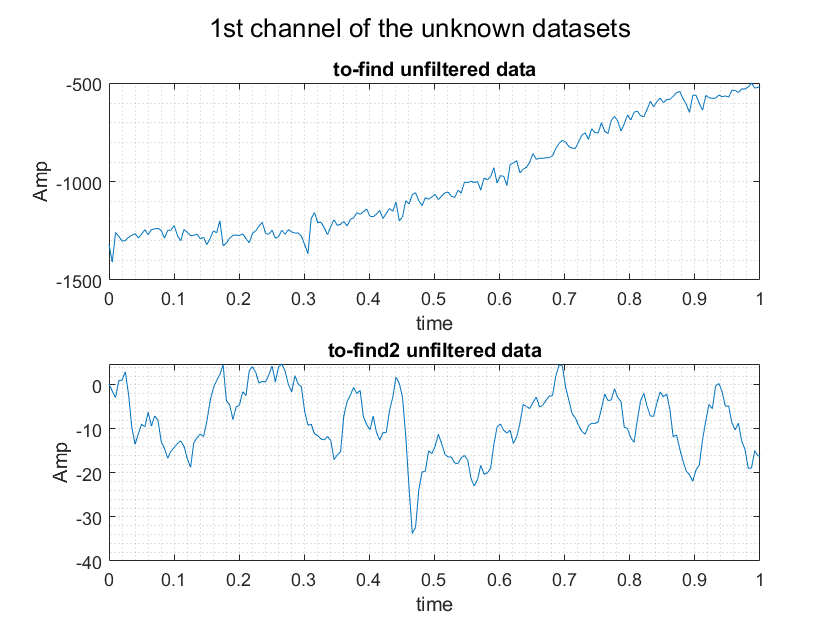

   for j = 1:2
    Fs = unknown(j).Fs(1);
    Ts = 1/Fs;    
    Ns = unknown(j).Duration;
    df = 1/(Ns * Ts);
    f = (-Ns/2:Ns/2-1)*df;
    df = fftshift(fft(unknown(j).Data(:,1)));
    epoch = (0:Ns-1)*Ts;    
    subplot(2,1,j)
     plot(f,abs(df(:,1)))
    xlabel("Hz");
    ylabel("Amp in Freq Domain");
    title(sprintf('raw data, stage%d', j-1));
    xlim([0 16])
    grid minor
   end   
  sgtitle ("1st channel of the unknown datasets")
subplot(2,1,1)
plot(epoch, to_find.Data(:,1))
xlabel("time");
ylabel("Amp");
xlim([0 1])
title("to-find unfiltered data");
grid minor
subplot(2,1,2)
plot(epoch, to_find2.Data(:,1))
xlabel("time");
ylabel("Amp");
xlim([0 1])
title("to-find2 unfiltered data");
grid minor